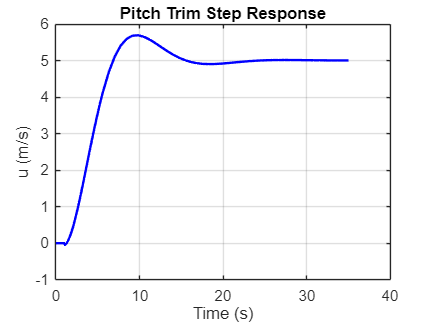

clear
clc


% 0 Controller value

Kp_1 = 7.80;

Kp_2 = -3.5;

Ki_2 = -0.088;

Kp_3 = -0.040;

% 1 Run model
out = sim('Pitch_Trim.slx');

% 2 Extract time and signal data
t = out.u.Time;      % Time vector
u = out.u.Data;      % Pitch rate (rad/s)

% 3 Compute step response characteristics

% Plot for verification
figure;
plot(t, u, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('u (m/s)');
title('Pitch Trim Step Response');
grid on;


% Compute step response characteristics
info = stepinfo(u, t);
disp('Step Response Characteristics:');

Step Response Characteristics:


disp(info);

         RiseTime: 3.9793
    TransientTime: 14.5104
     SettlingTime: 14.5177
      SettlingMin: 4.6966
      SettlingMax: 5.6930
        Overshoot: 13.7986
       Undershoot: 0.8559
             Peak: 5.6930
         PeakTime: 9.8391

